# Exercises: Anonymous Functions

**Task 1:** Define an anonymous function for $f(x)=cos(x)\cdot sin(y)$ using a function handle.

f=@(x,y) cos(x).*sin(y);

Make a surface plot of f(x,y) for x,y=[0:0.1:10] to check the implementation.

**Hint: **To plot the function on a grid you will have to use the builtin function meshgrid.

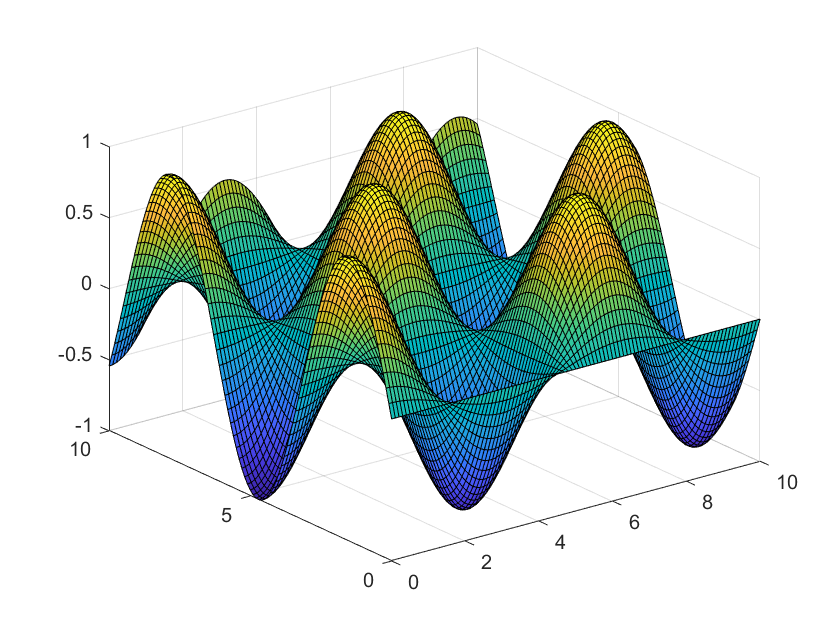

[X,Y]=meshgrid(0:0.1:10);
surf(X,Y,f(X,Y))

**Task 2*:** Implement the piecewise defined function $g\left(x\right)=-1\;\mathrm{for}\;x<3\pi ,\mathrm{cos}\left(x\right)\;\mathrm{for}\;-3\pi <x<4\pi ,1\;\mathrm{for}\;x>4\pi$using a function handle.

**Hint:** use the fact that comparison statements like (x>5) evaluate to 1 if true and zero if false. They can thus be used as prefactors.

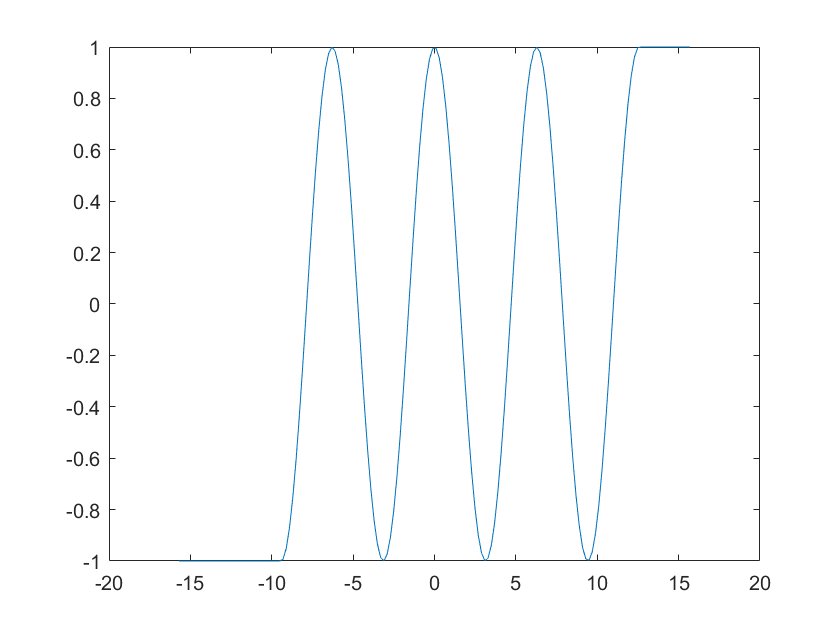

% define this function using a function handle and logical operators
g=@(x) -(x<-3*pi)+((x<4*pi).*(x>-3*pi)).*cos(x)+(x>4*pi);

x=[-5*pi:0.2:5*pi];
plot(x,g(x))